# Case0：一个风电站

clc
clear
close

## Environmental statement and general description

### 1. 建一个风场

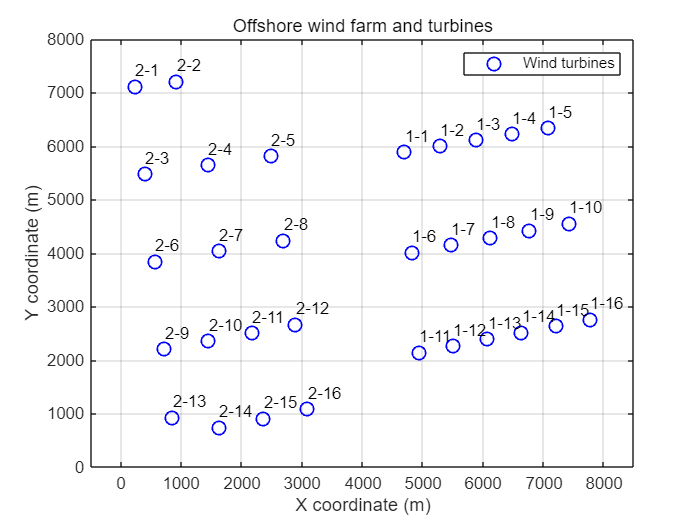

load points.mat
figure;
plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Wind turbines','MarkerSize',8,'LineWidth',1);
for i=1:length(points)
    if i>length(points) / 2
        part = 1;
        number = i-length(points) / 2;
    else
        part = 2;
        number = i;
    end
    text(points(i, 1), points(i, 2)+300, [num2str(part),'-',num2str(number)]);
end
axis([-500 8500 0 8000])
hold on;

title('Offshore wind farm and turbines');
xlabel('X coordinate (m)');
ylabel('Y coordinate (m)');
legend;
grid on;

### 2. 随机任务点

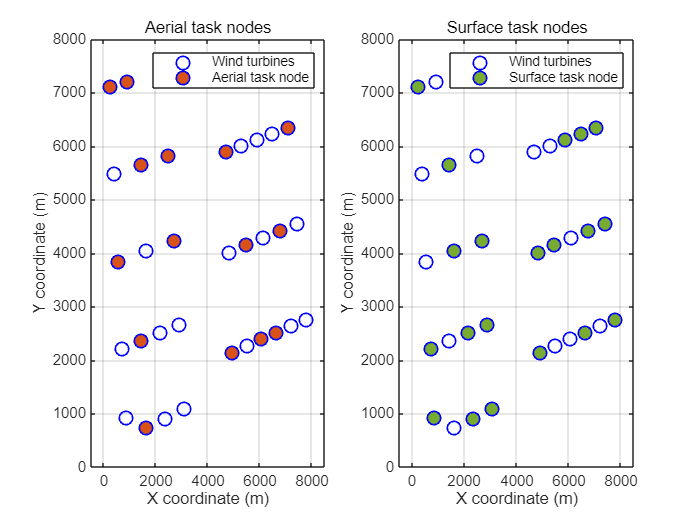

% 随机抽样出两个点集，允许重复
close
numSamplesAir = 15; % 每个点集的样本数量
numSamplesSur = 20; % 每个点集的样本数量

rng('shuffle'); % 初始化随机数生成器
load Wind_sample2.mat
% sampleIndicesAir = randperm(size(points, 1), numSamplesAir);
% sampleIndicesSur = randperm(size(points, 1), numSamplesSur);
% 
% sampleSetAir = points(sampleIndicesAir, :);
% sampleSetSur = points(sampleIndicesSur, :);

close 
% 绘制原始点阵和抽样点集
subplot(1,2,1);
plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Wind turbines','MarkerSize',8,'LineWidth',1);
hold on;
plot(sampleSetAir(:, 1), sampleSetAir(:, 2), 'bo', 'DisplayName', 'Aerial task node','MarkerFaceColor',"#D95319",'MarkerSize',8,'LineWidth',1);
%plot(sampleSetSur(:, 1), sampleSetSur(:, 2), 'o', 'DisplayName', 'Surface task node','MarkerFaceColor',"#77AC30",'MarkerSize',8,'LineWidth',1);
axis([-500 8500 0 8000])
title('Aerial task nodes');
xlabel('X coordinate (m)');
ylabel('Y coordinate (m)');
legend;
grid on;

subplot(1,2,2);
plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Wind turbines','MarkerSize',8,'LineWidth',1);
hold on;
%plot(sampleSetAir(:, 1), sampleSetAir(:, 2), 'o', 'DisplayName', 'Aerial task node','MarkerFaceColor',"#D95319",'MarkerSize',8,'LineWidth',1);
plot(sampleSetSur(:, 1), sampleSetSur(:, 2), 'bo', 'DisplayName', 'Surface task node','MarkerFaceColor',"#77AC30",'MarkerSize',8,'LineWidth',1);
axis([-500 8500 0 8000])
title('Surface task nodes');
xlabel('X coordinate (m)');
ylabel('Y coordinate (m)');
legend;
grid on;
hold off

## Global multi-layer task allocation framework: ATG-NSC-SOM

### 1. 建一个风场

### 2. Air点集组合

% 为每个点生成随机代价
numPoints = size(sampleSetAir, 1);
costs = 800*ones(numPoints, 1);

% 初始化边权重矩阵
weightMatrix = inf*ones(numPoints, numPoints);

% 计算Air边权重矩阵
for i = 1:numPoints
    for j = i+1:numPoints
        % 计算欧几里得距离
        distance = norm(sampleSetAir(i, :) - sampleSetAir(j, :)) ;
        % 计算两个点的代价平均数
        avgCost = (costs(i) + costs(j)) / 2;
        % 计算边的权重
        weight = distance + avgCost;
        % 填充权重矩阵
        weightMatrix(i, j) = weight;
        weightMatrix(j, i) = weight;
    end
end

% 初始化边权重矩阵
distanceMatrix = inf*ones(numPoints, numPoints);

% 计算Air边权重矩阵
for i = 1:numPoints
    for j = i+1:numPoints
        % 计算欧几里得距离
        distance = norm(sampleSetAir(i, :) - sampleSetAir(j, :))  ;
        % 计算边的权重
        weight = distance;
        % 填充权重矩阵
        distanceMatrix(i, j) = weight;
        distanceMatrix(j, i) = weight;
    end
end
distanceMatrix=distanceMatrix;

### 初始化组

remainingPoints = 1:numPoints;
groups = {};
groups_cost = {};
remainingCosts = costs;

% 遍历寻组
while sum(remainingPoints) ~= 0 

    % 找到最短的一个任务点
    [nowCost,nowIdx] = min(remainingCosts);

    % 本组的现有点和总代价
    bestGroup = nowIdx;
    bestCost  = nowCost;
    
    % 去掉这个点
    remainingPoints(nowIdx) = 0;
    remainingCosts(nowIdx) = inf;
    distanceMatrix(:,nowIdx) = inf;
    
    TempSumCost = nowCost;

    % 对剩下点的距离排序
    Weilist = distanceMatrix(bestGroup,:);
    [Weilist,lists] = sort(Weilist);

    i=1;
    % 开始以这个点为基础，找到不超过T的最大
    while 1
        nextIdx = lists(i);
        short = findshortestDis(nextIdx, bestGroup, distanceMatrix);
        TempSumCost = TempSumCost + short + costs(nextIdx);
        if TempSumCost >= 5000 
            break
        end
        distanceMatrix(:,nextIdx) = inf;
        remainingPoints(nextIdx) = 0;
        remainingCosts(nextIdx) = inf; 
        bestGroup = [bestGroup, nextIdx];
        bestCost  = TempSumCost;
        i=i+1;
    end
    groups{end+1} = bestGroup; 
    groups_cost{end+1} = bestCost;
end


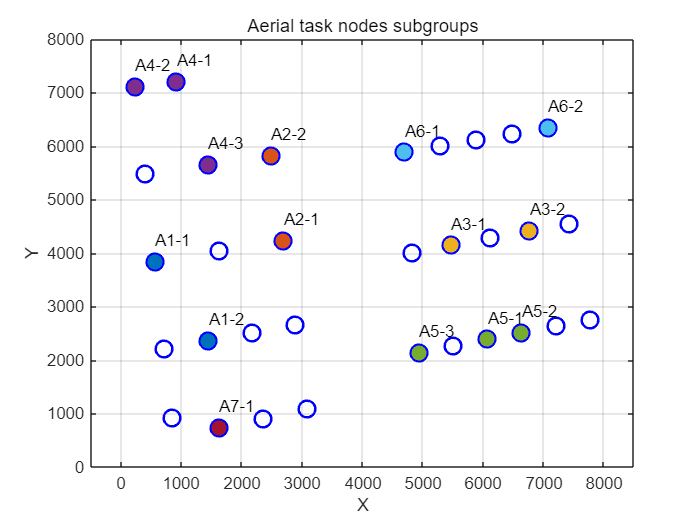

close 
figure;
Coulor=[0 0.4470 0.7410;0.8500 0.3250 0.0980;0.9290 0.6940 0.1250;0.4940 0.1840 0.5560;0.4660 0.6740 0.1880;0.3010 0.7450 0.9330;
    0.6350 0.0780 0.1840;0 1 0;1 0 0;0 1 1;1 0 1;1 1 0];
figure;
plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Turbines','MarkerSize',10,'LineWidth',1.5);
hold on;
for i=1:7
    AA=cell2mat(groups(i));
    plot(sampleSetAir(AA, 1), sampleSetAir(AA, 2),'bo', 'DisplayName', ['groups',num2str(i)],'MarkerFaceColor',Coulor(i,:),'MarkerSize',10,'LineWidth',1);
    for j = 1:length(AA)
        text(sampleSetAir(AA(j), 1), sampleSetAir(AA(j), 2)+400, ['A',num2str(i),'-',num2str(j)] );
    end
end

hold off;
axis([-500 8500 0 8000])
title('Aerial task nodes subgroups');
xlabel('X');
ylabel('Y');
%legend('Turbines','subgroups');
grid on;

### 3. 计算每个组内的重心

ga=zeros(size(groups,2),2);
cost_ga=zeros(size(groups,2),1);
for i=1:size(groups,2)
    AA=cell2mat(groups(i));
    xx=sum(sampleSetAir(AA,1))/length(AA);
    yy=sum(sampleSetAir(AA,2))/length(AA);
    ga(i,:) = [xx, yy];
    cost_ga(i) = cell2mat(groups_cost(i));
end

%% 重组海面任务集合
Expand_node = [sampleSetSur;ga];
costs_sur = 800*ones(numSamplesSur, 1);
Expand_Cost = [costs_sur; cost_ga];

%% 谱聚类！
% 初始化边权重矩阵
weightMatrix = zeros(size(Expand_node,1), size(Expand_node,1));

% 计算Air边权重矩阵
for i = 1:numPoints
    for j = i+1:numPoints
        % 计算欧几里得距离
        distance = norm(Expand_node(i, :) - Expand_node(j, :));
        % 计算两个点的代价平均数
        avgCost = (Expand_Cost(i) + Expand_Cost(j)) / 2;
        % 计算边的权重
        weight = distance + avgCost;
        % 填充权重矩阵
        weightMatrix(i, j) = weight;
        weightMatrix(j, i) = weight;
    end
end


for j=1:length(Expand_Cost)
    AcAA(j)=sum(weightMatrix(j,:))/length(Expand_Cost);
end


dataSet = [Expand_node];
numPoints=size(dataSet,1);
num_clusters=4;
Sigma=1;

idx = kmeans(dataSet,num_clusters);
%idx = spectralcluster(weightMatrix,num_clusters,'Distance','precomputed');


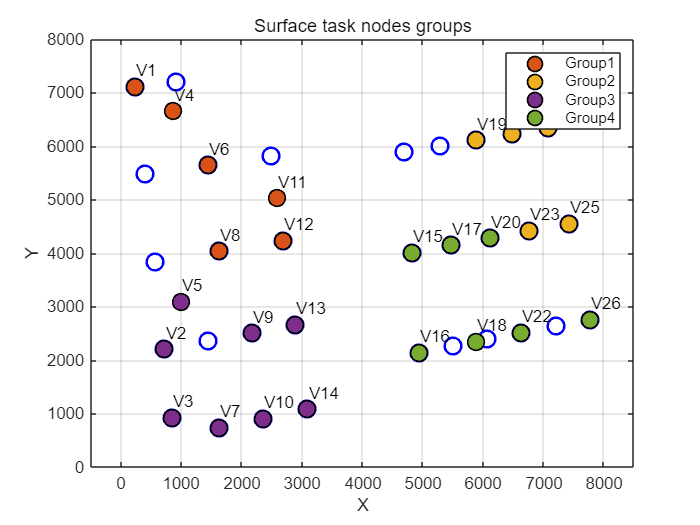

close
load Wind_idx.mat

plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Turbines','MarkerSize',10,'LineWidth',1.5);
hold on;
for i=1:num_clusters
    plot(dataSet(idx==i,1),dataSet(idx==i,2),'ko', 'DisplayName', ['groups',num2str(i)],'MarkerFaceColor',Coulor(i+1,:),'MarkerSize',10,'LineWidth',1)
end

l1 = unique(dataSet, 'rows');
for j=1:length(l1)
    text(l1(j,1)+10, l1(j,2)+300, ['V',num2str(j)] );
end

hold off
legend('','Group1','Group2','Group3','Group4')
axis([-500 8500 0 8000])
title('Surface task nodes groups');
xlabel('X');
ylabel('Y');
grid on;

CC=[];
for i=1:num_clusters
    CC(i)=sum(Expand_Cost(idx==i));
end

## 4. SOM路径任务调度

for i=1:length(CC)
    l1=[dataSet(idx==i,1),dataSet(idx==i,2)];  % 本聚类下的目标点
    l1 = unique(l1, 'rows');
    [list,roat] = TSP_ACSolution(l1); % 本聚类做TSP，得到最优排序和最优路径
    %Group = [dataSet(idx==i,1),dataSet(idx==i,2)];
    USV_order{i} = [l1(list,1),l1(list,2)]; 
    USV_cost{i} = roat + CC(i);
end


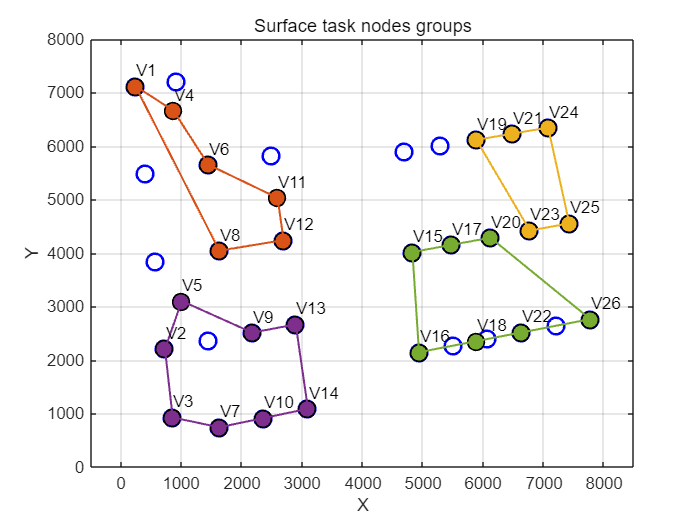

close
figure
plot(points(:, 1), points(:, 2), 'bo', 'DisplayName', 'Turbines','MarkerSize',10,'LineWidth',1.5);
hold on;
for i=1:num_clusters
    plot(dataSet(idx==i,1),dataSet(idx==i,2),'ko', 'DisplayName', ['groups',num2str(i)],'MarkerFaceColor',Coulor(i+1,:),'MarkerSize',10,'LineWidth',1)
    list = USV_order{i};
    list = [list;list(1,:)];
    plot(list(:,1),list(:,2),'color',Coulor(i+1,:),'LineWidth',1.2);
end
l1 = unique(dataSet, 'rows');
for j=1:length(l1)
    text(l1(j,1)+10, l1(j,2)+300, ['V',num2str(j)] );
end

hold off
axis([-500 8500 0 8000])
title('Surface task nodes groups');
xlabel('X');
ylabel('Y');
grid on;